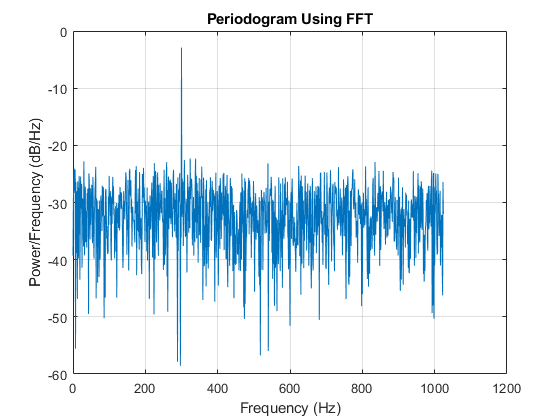

fs = 2048;
t = 0:1/fs:1-1/fs;
x = cos(2*pi*300*t) + randn(size(t));

N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(x):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")